# Projetos via realimentação de estados

**Sistema Realimentados**

Seja o sistema dado por:


$$\dot{x}=Ax+Bu$$



$$y=Cx$$



$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-10 & -17 & -8
\end{array}\right\rbrack$$
  
$$B=\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$
 
$$C=\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack$$
 
$$D=0$$


A=[0 1 0;0 0 1;-10 -17 -8];
B=[0;0;1];
C=[10 0 0];
D=0;
s1=ss(A,B,C,D)

s1 =
 
  A = 
        x1   x2   x3
   x1    0    1    0
   x2    0    0    1
   x3  -10  -17   -8
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1  10   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


g1=tf(s1)

g1 =
 
            10
  -----------------------
  s^3 + 8 s^2 + 17 s + 10
 
Continuous-time transfer function.
Model Properties


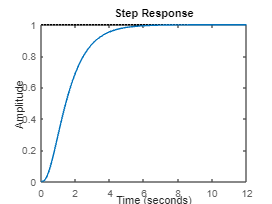

figure;
step(g1);

Vejam que se fizermos, s2=ss(g1), resulta

s2=ss(g1)

s2 =
 
  A = 
          x1     x2     x3
   x1     -8  -4.25  -1.25
   x2      4      0      0
   x3      0      2      0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
         x1    x2    x3
   y1     0     0  1.25
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Ou seja, se os estados de s1 são $x_1,x_2,x_3$, são diferentes dos estados de s2, mas ambos tem a mesma FT g1(s).

Por fim, para acessar as matrizes de s2, basta usar s2.A, s2.B, etc.

**Realimentação de estados**

Como o sistema responde em 6 segundos, escolheremos tempo de estabilização Ts=2s e UP=4.3%.

UP=4.3;
Ts=0.2;
a=log(UP/100);
zeta=sqrt(a^2/(pi^2+a^2))

zeta = 0.7077

wn=4/(Ts*zeta)

wn = 28.2620

polos=roots([1 2*zeta*wn wn^2])

polos =  -20.0000 +19.9685i
 -20.0000 -19.9685i


Escolha localizações para p3: a escolha deve permitir atender as especificações.

p3=-25;
polos=[polos; p3]

polos =  -20.0000 +19.9685i
 -20.0000 -19.9685i
 -25.0000 + 0.0000i


**Realimentação de estados**

K=place(A,B,polos)

K = 1.0e+04 *

    1.9958    0.1782    0.0057


**Sistema em malha fechada**

s1mf=ss(A-B*K,B,C,D)

s1mf =
 
  A = 
               x1          x2          x3
   x1           0           1           0
   x2           0           0           1
   x3  -1.997e+04       -1799         -65
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1  10   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


**Função de transferência de malha fechada**

g1mf=tf(s1mf)

g1mf =
 
                 10
  --------------------------------
  s^3 + 65 s^2 + 1799 s + 1.997e04
 
Continuous-time transfer function.
Model Properties


**Simulação ao degrau em malha fechada**

Confira o atendimento da especificação feita:

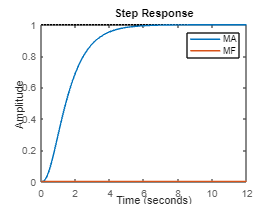

figure;
step(s1,s1mf);legend('MA','MF');

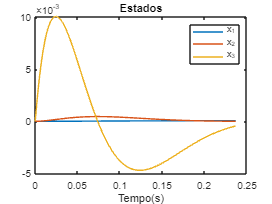

[y,t,x]=step(s1mf); % Gera os estados
u=1-K*(x'); % Calcula o sinal de controle
figure;
plot(t,x);legend('x_1','x_2','x_3');
title('Estados');xlabel('Tempo(s)');

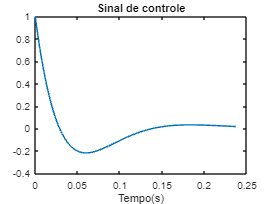

figure;plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');

**Ganho da FT de malha fechada**

Ao  implementar a realimentação de estados, o ganho da função de transferência ficou

p1=dcgain(g1mf)

p1 = 5.0079e-04

Portanto, ao se aplicar um degrau unitário a saída em regime será igual a p1, ou seja, haverá erro em regime.

Uma forma de amenizar este efeito é multiplicar a referência pelo inverso desse valor. 

Dessa forma, a saída será igual ao valor desejado.

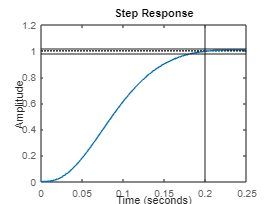

figure;
step((1/p1)*g1mf);yline(1.02);yline(0.98);xline(Ts);

Neste caso, o sinal de controle é dado por 


$$u(t)=(1/p_1)r(t)-Kx(t)$$


Faremso agora a simulação assumindo que o sinal de controle esteja limitado por $|u(t)|\leq100$.

Observe que a resposta não atende a especificação, e deve-se rever o projeto.

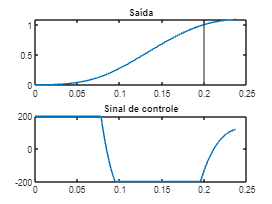

sat=200;
[y,t,u] = simula_t6(s1,K,p1,sat);
figure
subplot(211);plot(t,y);title('Saída');xline(Ts);
subplot(212);plot(t,u);title('Sinal de controle');

**Realimentação integral de estados**

O integrador (polo na origem) no sinal de erro garante que a saída y tenda para a referência se o sistema for estável, ou seja, todos os polos estão no SPE. Tem-se, portanto, um sistema tipo1, com a FT  $\frac{k_4}{s}C(sI-A+BK)^{-1}B$,  sendo $K=\left\lbrack \begin{array}{ccc}
k_1  & k_2  & k_3 
\end{array}\right\rbrack$.

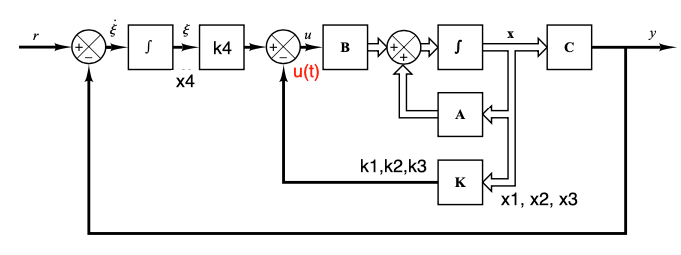

Usando os dados anteriores, constroi-se o sistema aumentado, ou seja, com um estado adicional devido ao polo na origem. Agora o sistema terá 4 estados. 

A1=[A [0;0;0];[-C 0]]

A1 =      0     1     0     0
     0     0     1     0
   -10   -17    -8     0
   -10     0     0     0


B1=[B;0];
Br=[0 ;0;0;1]; % Br é diferente de B1, ver notas de aula
C1=[C 0];
D1=D;
sima=ss(A1,B1,C1,D1);

Altere a localização de p4 e observe o efeito na resposta y(t)=x1(t) e no sinal de controle u(t).

polos(3)=-33;
p4=-35;
polos4=[polos;p4 ]

polos4 =  -20.0000 +19.9685i
 -20.0000 -19.9685i
 -33.0000 + 0.0000i
 -35.0000 + 0.0000i


K1=place(A1,B1,polos4)

K1 = 1.0e+05 *

    1.0050    0.0466    0.0010   -0.9225


**Sistema em malha fechada**

simf=ss(A1-B1*K1,Br,C1,D1)

simf =
 
  A = 
               x1          x2          x3          x4
   x1           0           1           0           0
   x2           0           0           1           0
   x3  -1.005e+05       -4674        -108   9.225e+04
   x4         -10           0           0           0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1  10   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


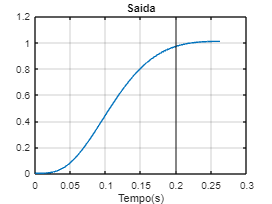

[y,t,x]=step(simf);
u=-K1*(x');
figure;plot(t,y);xline(Ts);grid;
title('Saida');xlabel('Tempo(s)');

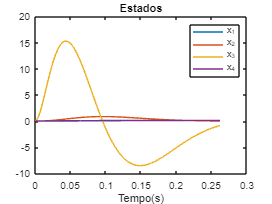

figure;
plot(t,x);legend('x_1','x_2','x_3','x_4');
title('Estados');xlabel('Tempo(s)');

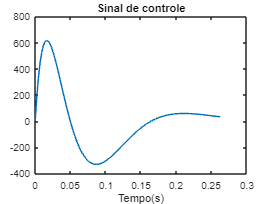

figure;
plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');

Simulação com a saturação agora. Observe a saturação no sinal de controle e que agora o tempo de estabelecimento não é atendido.

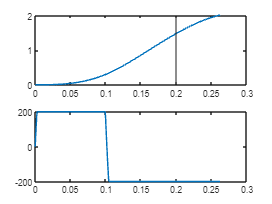

[y,t,u] = simula_t6(sima,K1,1,sat);
figure;
subplot(211);plot(t,y);xline(Ts);
subplot(212);plot(t,u);